% Modelling ML

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);

% ********** 1) Baseline Models **********

% 1a) Baseline Decision Tree
% Train
dt_base = fitctree(X_train, y_train);
% Evaluate baseline tree
y_pred = predict(dt_base, X_test);
[accuracy, precision, recall, specificity, f1] = binary_eval_metrics(y_test, y_pred) %#ok<ASGLU> 

accuracy = 0.9206

precision = 0.1429

recall = 0.0943

specificity = 0.9677

f1 = 0.1136

% 1b) Baseline Random Forest
% Train
rf_base = fitcensemble(X_train, y_train, 'Method', 'Bag');
% Evaluate
y_pred = predict(rf_base, X_test);
[accuracy, precision, recall, specificity, f1] = binary_eval_metrics(y_test, y_pred) %#ok<ASGLU> 

accuracy = 0.9450

precision = 0

recall = 0

specificity = 0.9989

f1 = 0

% 1c) Baseline KNN
% Train
knn_base = fitcknn(X_train, y_train, 'NumNeighbors', 2 ,'Standardize',1);
% Evaluate baseline knn
y_pred = predict(knn_base, X_test);
[accuracy, precision, recall, specificity, f1] = binary_eval_metrics(y_test, y_pred)

accuracy = 0.9460

precision = NaN

recall = 0

specificity = 1

f1 = 0

% ********** 2) Tuned Models **********

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |      MinLeaf |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |    0.028924 |           1 |           1 |            7 |            3 |


|    2 | Accept |           1 |     0.01379 |           1 |           1 |           22 |           22 |
|    3 | Accept |           1 |    0.013326 |           1 |           1 |            3 |           20 |
|    4 | Best   |     0.89535 |    0.019301 |     0.89535 |      0.9045 |           15 |           15 |
|    5 | Accept |     0.89535 |    0.021023 |     0.89535 |     0.89536 |           15 |           15 |
|    6 | Accept |           1 |    0.010847 |     0.89535 |     0.89536 |            5 |            9 |
|    7 | Accept |     0.89535 |     0.01126 |     0.89535 |     0.89535 |           14 |            2 |
|    8 | Accept |           1 |    0.012058 |     0.89535 |     0.89535 |           14 |           25 |
|    9 | Accept |     0.89535 |    0.012151 |     0.89535 |     0.89535 |           15 |           16 |
|   10 | Accept |     0.89535 |    0.014499 |     0.89535 |     0.89533 |           15 |            2 |
|   11 | Accept |     0.89535 |    0.012138 |     0.89535 |     

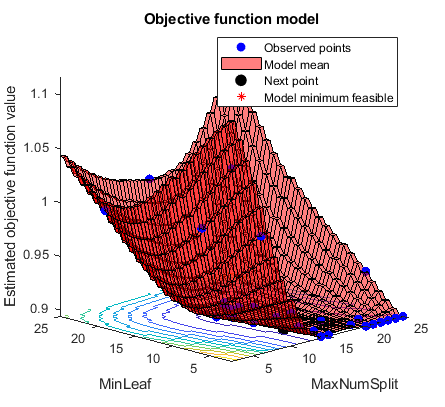

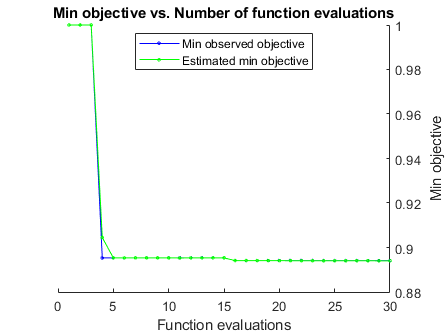


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 18.3153 seconds
Total objective function evaluation time: 0.427

Best observed feasible point:
    MaxNumSplit    MinLeaf
    ___________    _______

        25            2   

Observed objective function value = 0.89412
Estimated objective function value = 0.89417
Function evaluation time = 0.013367

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeaf
    ___________    _______

        21            2   

Estimated objective function value = 0.894
Estimated function evaluation time = 0.013856



% 2b) Optimized Tree
% Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[2,25],'Type','integer');
MinLeaf = optimizableVariable('MinLeaf',[2, 25],'Type','integer');
paramsTree = [MaxNumSplit; MinLeaf];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)f1_loss_dt(params,X_train,y_train),paramsTree,...
    'AcquisitionFunctionName','expected-improvement-plus','Verbose',1);

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)f1_loss_dt(params,X_train,y_train),paramsTree,...
    'AcquisitionFunctionName','expected-improvement-plus','Verbose',1);

function f1 = f1_loss_dt(params, X_train, y_train)
        model=fitctree(X_train,y_train,'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeaf);
        
        % Calculate F1 score
        y_pred = predict(model,X_train);
        [~, ~, ~, ~, f1] = binary_eval_metrics(y_train, y_pred);
        f1=1-f1;  % Convert to f1-"loss"
end

function [acc, prec, rec, spec, f1] = binary_eval_metrics(y_test, y_pred)
    % Evaluation metrics for binary classification
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);
    %confusionchart(cmat);

    % Statistics of interest for confusion matrix
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    f1 = tp / (tp + 0.5*(fp + fn));
end